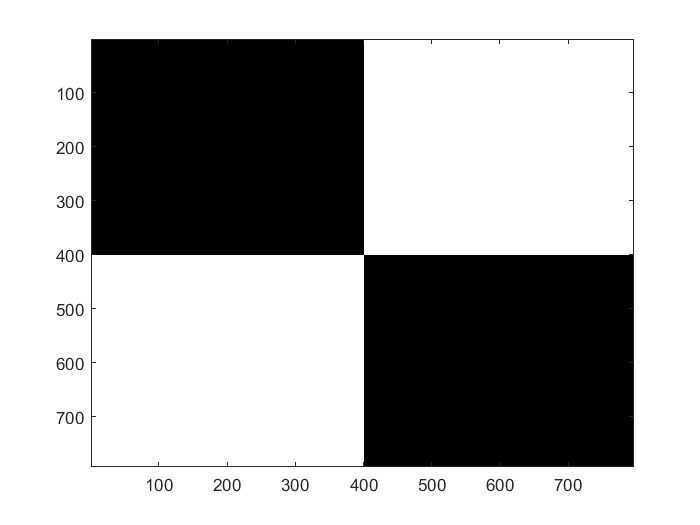

lit = imread('checkers.jpg');
T = double(lit(:,:,1));
clf
imagesc(T); colormap('gray');

T(T == 0) = -1;
T(T == 255) = 1;
T(T >= 128) = 1;
T(abs(T) ~= 1) = -1;
imagesc(T);

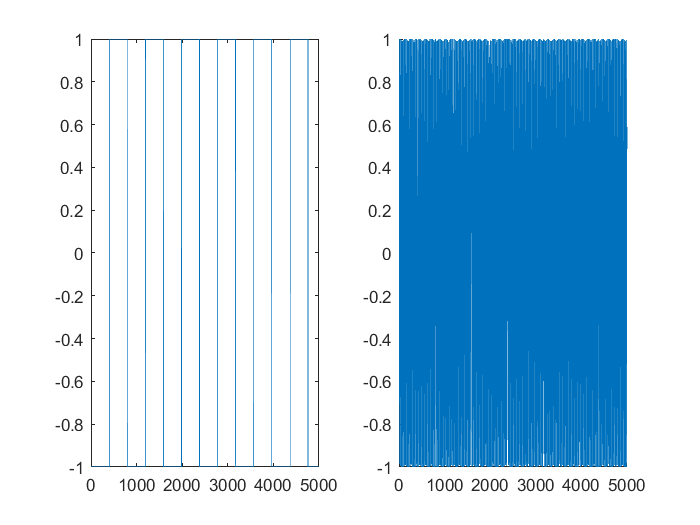

arrayT = reshape(T,631228,1);
clf
subplot(1,2,1);
plot(arrayT);
xlim([0,5000])
mt = arrayT;                            %array of data
sampleTime = 10;                        %Total length of sample in time
sampleRate = (length(mt))/(sampleTime); %Number of samples per second
t = linspace(0,sampleTime,length(mt));           %array keeping time
w = (sampleRate/3);                     %frequency of cosine wave
c = cos(w*t+(pi/4));                           %array containing carrier wave
xt = mt.*c';                            %assembled signal containing carrier and signal waves
subplot(1,2,2);
hold on
plot(xt)
xlim([0,5000])
hold off

phi = 0;
avWind = (100/w)/(1/sampleRate);
for k = (avWind+1):avWind:length(xt)
    yt1 = cos(w*t + phi).*xt';
    y1 = mean(yt1(k-avWind:k));
    yt2 = -sin(w*t + phi).*xt';
    y2 = mean(yt2(k-avWind:k));
    phi = 4*y1*y2 + phi;
end
phi

phi = 0.0986

demodXt = xt'.*cos(w'.*t + phi);
omc = (w*2*pi./sampleRate)*.2;
n = -1000:1000;
h = omc/pi*sinc(omc*n/pi);
filtX = 3.33*conv(demodXt,h, 'same');

y1 = [];
y2 = [];
y3 = [];
omc = (w*2*pi./sampleRate)*.2;
n = -1000:1000;
h = omc/pi*sinc(omc*n/pi);
y1 = xt.*cos(w.*t.');
y2 = xt.*sin(w*t.');
yc = 3.3333*conv(y1, h,'same');
ys = 3.3333*conv(y2, h, 'same');
z = yc+i*ys;
a = fftshift(fft(z.^2));
fs  = linspace(-pi, pi*(length(a)-1)/length(a), length(a));
clf
[tmp, ii] = max(abs(a));
wdelta = fs(ii)

wdelta = 2.4885e-06

theta = angle(a(ii))/2

theta = -0.7854

remod = cos(w.*t.'-wdelta.*t.'-theta).*xt;
omc = (w*2*pi./sampleRate)*.2;
n = -1000:1000;
h = omc/pi*sinc(omc*n/pi);
demodulated = 3.33*conv(remod,h, 'same');

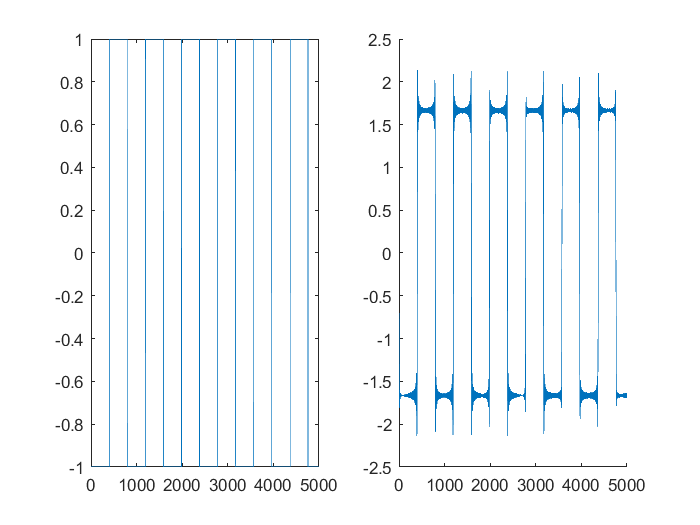

clf
subplot(1,2,1);
plot(arrayT);
xlim([0,5000])
subplot(1,2,2);
hold on
plot(demodulated)
xlim([0,5000])
hold off

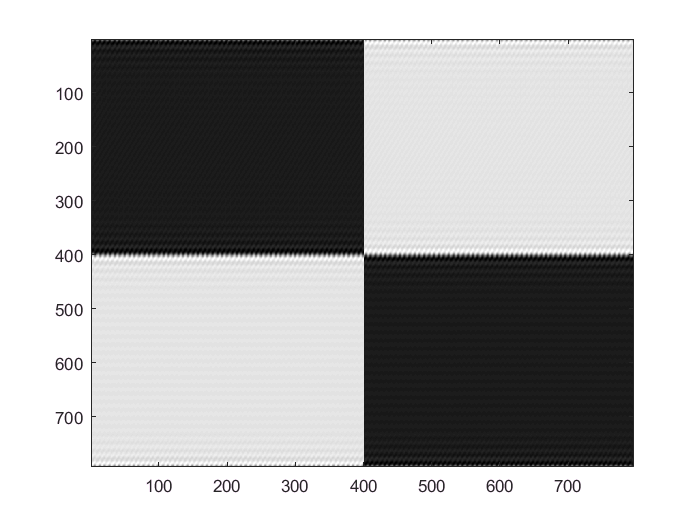

recievedIm = reshape(filteredXt,793,796);
clf
imagesc(recievedIm);

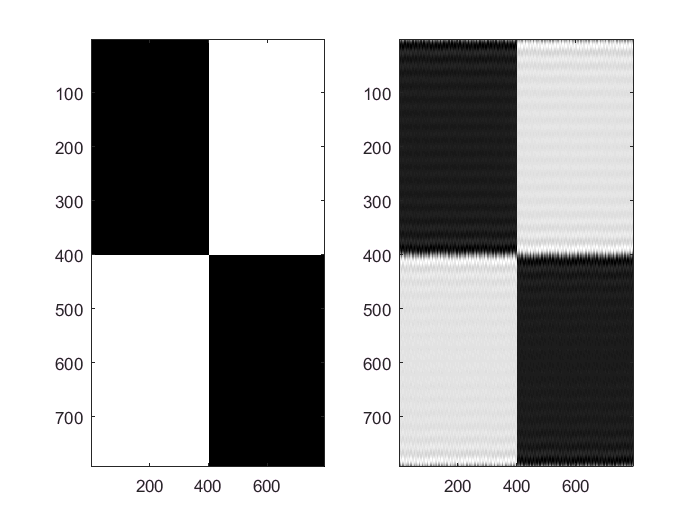

clf
subplot(1,2,1);
imagesc(T);
subplot(1,2,2);
imagesc(recievedIm);